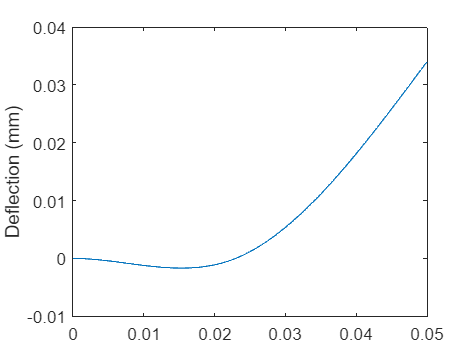

clear; clc; clf; close all
E = 70e9;
R = 0.005;
I=0.5 * pi * R^4;

x_b = 0.023;
x_c = 0.05;

V = 0.8 * sqrt(1.4 * 287 * 297);
Cd = 1.2;
P = 0.5 * 1.225 * (0.11 + 0.045) / 2 * 0.05 * V^2 * Cd;

F_a = - 3 / 2 * (x_b - x_c) / x_b * P;
F_b = - F_a - P;
M_a = -F_a / 3 * x_b;

v = @(x) (0.5 * M_a * x.^2 + 1/6 * F_a * x.^3 + 1/6 * F_b * (x > x_b) .* (x - x_b) .^3) / (E*I);
M = @(x) M_a + F_a * x + F_b * (x > x_b) .* (x - x_b);
stress = @(x) - M(x) / I * R;

x = 0:0.0001:x_c;
plot(x, v(x) * 1000);
ylabel("Deflection (mm)")

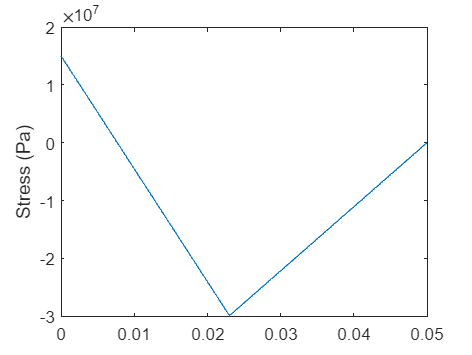

plot(x, stress(x));
ylabel("Stress (Pa)")